# **Controlador Basado en Dinamicas Poblacionales: Modelo de Hovorka**

**Elaborado por: **Manuela María Muriel Tobar, David Andrés Ojeda Guzmán

**Universidad de Nariño**

El código implementa un controlador basado en dinámicas poblacionales aplicado al modelo mínimo de Bergman para el control de la glucosa en sangre.

El enfoque utiliza tres hábitats de control, que representan distintas estrategias o "comportamientos" del páncreas artificial frente a diferentes condiciones metabólicas.

clear variables; close all; clc;

El control se basa en el **principio del replicador** de la teoría de juegos evolutiva.

Cada hábitat tiene una "aptitud" o **función de fitness** $f_{i}(t)$, y su proporción poblacional $x_{i}(t)$ evoluciona según:


$$\dot{x}_i = \beta x_i \left( f_i - \bar{f} \right) + \varepsilon \left( \frac{1}{3} - x_i \right)$$


donde:

$\beta$:  velocidad de adaptación del sistema

$\bar{f} = x_1 f_1 + x_2 f_2 + x_3 f_3$: fitness promedio de toda la población

$\varepsilon \left( \frac{1}{3} - x_i \right)$: Permite que, con el paso del tiempo, las demás estrategias sigan activas.

el termino de control total se obtiene como la combinacion de los habitats


$$u(t) = u_{\text{rep}} + u_{\text{meal}}$$


siendo:


$$u_{\text{rep}} = u_{\min} + (u_{\max} - u_{\min}) x_1
$$
$$
u_{\text{meal}} = \frac{1000}{CF} D_{\text{meal}}(t) x_3$$


donde $CF = 40 \frac{mg}{dL}U$ el cual es el factor de correccion glucosa insulina

ctrl = struct();

**Definición de los hábitats:**

**Hábitat 1 — Aplicar insulina basal**

Activo por fuera de las comidas. Busca reducir el error cuando $e > 0$


$$f_1 = w_{H1} \tanh \left( g_1 \left( K_{p1} e^+ + K_{i1} z + K_{d1} \dot{e}^+ \right) \right)$$


**Hábitat 2 — Suspender insulina**

Siempre activo, responde ante glucosa baja ($e<0$) 


$$f_2 = w_{H2} \tanh \left( g_2 \left( K_{p2} e^- + K_{i2} (-z) + K_{d2} \dot{e}^- \right) \right)$$


**Hábitat 3 — Bolus**

Activo solo durante comidas. Este habitat proporciona dosis rapidas correctivas en funcion de la ingesta de glucosa.


$$f_3 = w_{H3} \tanh \left( g_3 \left( K_{\text{meal}} D_{\text{meal}})$$


**Funciones de fitness suavizadas**

La respuesta de cada funcion de fitness se filtra mediante una funcion tangente hiperbolica, para evitar oscilaciones. Evitando los cambios abruptos de población.

%Parametros del Replicador
ctrl.beta = 3.0; %Velocidad de replicación      
ctrl.eps = 2.4e-4; %Factor de diversidad    
ctrl.kp1 = 0.53;  ctrl.ki1 = 36e-4; ctrl.kd1 = 12.6;  % Hábitat 1 (basal)
ctrl.kp2 = 0.63;  ctrl.ki2 = 0.02e-4; ctrl.kd2 = 21.7; % Hábitat 2 (suspender)
ctrl.kp3 = 0.11;  ctrl.ki3 = 1; ctrl.kd3 = 0;         % Hábitat 3 (bolus)

Parametros de las comidas

ctrl.kmeal = 24;    
ctrl.u_min = 0;
ctrl.u_max = 32;
ctrl.meals = [40, 60, 50];
ctrl.meal_times = [8*60, 12*60, 20*60];
ctrl.gamma_shape = 3.5;
ctrl.gamma_rate = 0.06;
ctrl.meal_scaling = 1;
ctrl.meal_window_half = 15;

Suavizamiento de las fitness

ctrl.gain_tanhf1 = 0.048; 
ctrl.gain_tanhf2 = 0.060;  
ctrl.gain_tanhf3 = 0.055;  
ctrl.CF_mg_dL_per_U = 40;

Parametros del modelo de Hovorka

hov = struct();
hov.k12 = 0.066;
hov.ka1 = 0.006;
hov.ka2 = 0.06;
hov.ka3 = 0.03;
hov.ke = 0.138;
hov.VI = 0.12;
hov.VG = 0.16;
hov.AG = 0.8;
hov.t_maxG = 40;
hov.t_maxI = 55;
hov.EGP0 = 0.0161;
hov.F01 = 0.0097;
hov.weight_kg = 70;

Condiciones iniciales del sistema

G0_mmol_L = 5.55;
y0 = zeros(8,1);
y0(1) = hov.VG * G0_mmol_L;
y0(2) = 0;
y0(3) = 0;
y0(4) = 0;
y0(5) = 0;


Poblaciones iniciales

y0(6) = 0.4;  % x1 inicial más alta
y0(7) = 0.3;  % x2 inicial más baja
y0(8) = 0;

Simulación

tspan = 0:1:24*60;
opts = odeset('RelTol',1e-6,'AbsTol',1e-9);

Simulación

[t, Y] = ode45(@(t,y) control_replicador_comidas_HV(t,y,hov,ctrl), tspan, y0, opts);

Procesamiento de resultados

Q1 = Y(:,1);
G_mmolL = Q1 ./ hov.VG;
G_mg_dL = G_mmolL * 18.0156;

x1 = Y(:,6); x2 = Y(:,7); x3 = 1 - x1 - x2; x3 = max(0,x3);

% Calcular insulina aplicada en cada paso de tiempo
u_rep_vec = zeros(length(t), 1);
u_meal_vec = zeros(length(t), 1);
u_total_vec = zeros(length(t), 1);
Dmeal_vec = zeros(length(t), 1);

for i = 1:length(t)
    % Calcular Dmeal para este tiempo
    Dmeal_g_min = compute_Dmeal(t(i), ctrl);
    Dmeal_vec(i) = Dmeal_g_min;
    
    % Calcular componentes de control
    u_rep_vec(i) = ctrl.u_min + (ctrl.u_max - ctrl.u_min) * x1(i);
    u_meal_vec(i) = (Dmeal_g_min / ctrl.CF_mg_dL_per_U) * 1000 * x3(i);
    u_total_vec(i) = min(max(u_rep_vec(i) + u_meal_vec(i), ctrl.u_min), ctrl.u_max);
end

% Calcular insulina acumulada
u_total_cumulative = cumtrapz(t, u_total_vec); % mU total acumulada
u_total_cumulative_U = u_total_cumulative / 1000; % U total acumulada

% Calcular insulina por hora
u_hourly = zeros(24, 1);
for hour = 1:24
    start_idx = (hour-1)*60 + 1;
    end_idx = min(hour*60, length(t));
    u_hourly(hour) = sum(u_total_vec(start_idx:end_idx)) / 1000; % U/hora
end

Calculo de metricas de desempeño

G_ref_vec = arrayfun(@(tt) smooth_glucose_reference(tt), t);
err = G_mg_dL - G_ref_vec;
IAE = trapz(t, abs(err))/1440;
ISE = trapz(t, err.^2)/1440;
ITAE = trapz(t, t .* abs(err))/1440;
TIR = mean((G_mg_dL >= 70) & (G_mg_dL <= 180)) * 100;
Hipo = mean((G_mg_dL < 70)) * 100;
Hiper = mean((G_mg_dL > 180)) * 100;

CV = 100 * std(G_mg_dL) / mean(G_mg_dL);

in_total = trapz(t, (u_total_vec/33));
D_total = t(end)- t(1);
in_prom = in_total/D_total;

fprintf('Métricas de control: IAE Norm=%.4f, ISE Norm=%.4f, ITAE Norm=%.2f, TIR=%.2f%%\n', IAE, ISE, ITAE, TIR);

Métricas de control: IAE Norm=1.3735, ISE Norm=5.6002, ITAE Norm=912.87, TIR=100.00%


fprintf('Métricas de clinicas: Hipo=%.2f%%, Hiper=%.2f%%,CV=%.2f%%', Hipo, Hiper, CV);

Métricas de clinicas: Hipo=0.00%, Hiper=0.00%,CV=13.60%

    Graficas

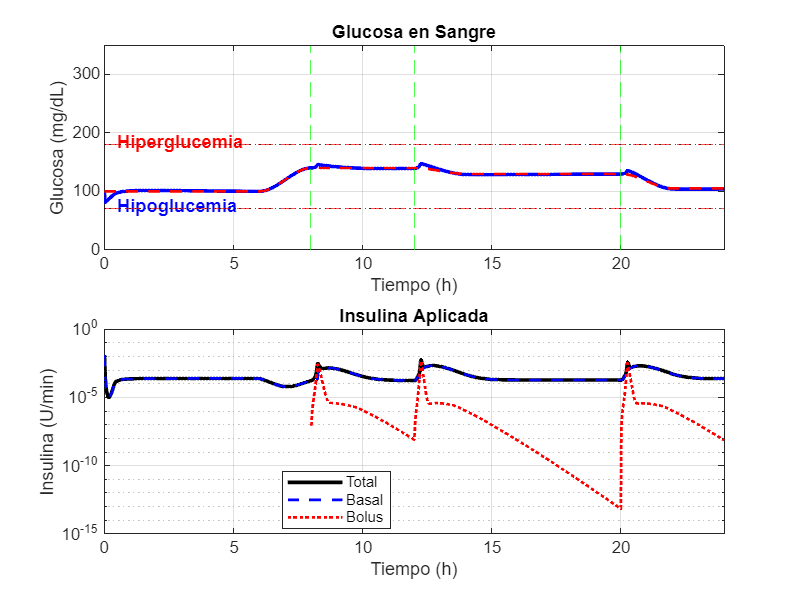

figure('Position', [50, 50, 1600, 1200]);

% Subplot 1: Glucosa
subplot(2,1,1);
plot(t/60, G_mg_dL, 'b-', 'LineWidth', 2);
hold on;
yline(70, 'r--'); yline(180, 'r--');
text(0.5,  75,'Hipoglucemia','Color','blue','FontWeight','bold');
text(0.5, 185,'Hiperglucemia','Color','red','FontWeight','bold','HorizontalAlignment','left');
plot(t/60, G_ref_vec, 'r--', 'LineWidth', 1.5);
yline(70, 'k:', 'Alpha', 0.7);
yline(180, 'k:', 'Alpha', 0.7);
for k=1:length(ctrl.meal_times)
    xline(ctrl.meal_times(k)/60, 'g--', 'Alpha', 0.7);
end
xlabel('Tiempo (h)'); ylabel('Glucosa (mg/dL)');
title('Glucosa en Sangre');
grid on; xlim([0 24]);ylim([0 350]);

% Subplot 2: Insulina aplicada
subplot(2,1,2);
plot(t/60, u_total_vec/1000, 'k-', 'LineWidth', 2, 'DisplayName', 'Total');
hold on;
plot(t/60, u_rep_vec/1000, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Basal');
plot(t/60, u_meal_vec/1000, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Bolus');
xlabel('Tiempo (h)'); ylabel('Insulina (U/min)');
title('Insulina Aplicada');
legend('Location', 'best');
grid on; xlim([0 24]);

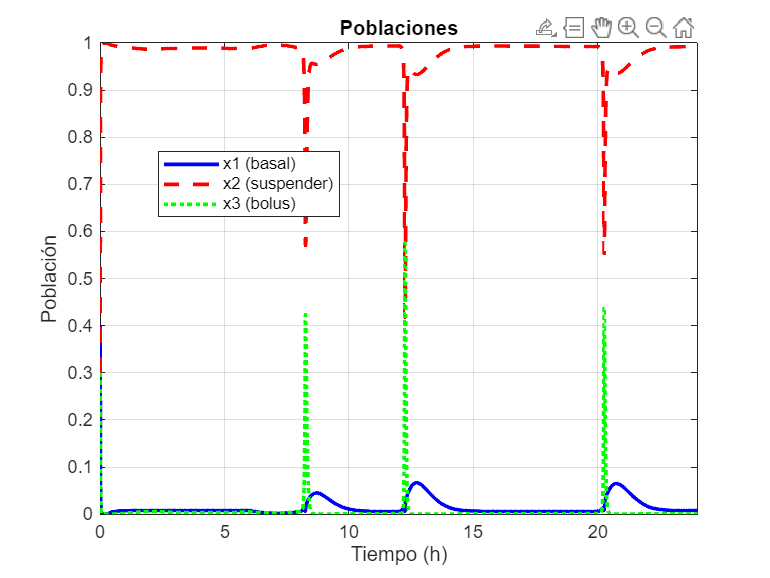


%plot 2: Poblaciones
figure;

plot(t/60, x1, 'b-', 'LineWidth', 2, 'DisplayName', 'x1 (basal)');
hold on;
plot(t/60, x2, 'r--', 'LineWidth', 2, 'DisplayName', 'x2 (suspender)');
plot(t/60, x3, 'g:', 'LineWidth', 2, 'DisplayName', 'x3 (bolus)');
xlabel('Tiempo (h)'); ylabel('Población');
title('Poblaciones');
legend('Location', 'best');
grid on; xlim([0 24]);

function dydt = control_replicador_comidas_HV(t,y,hov,ctrl)
    % Desempaquetar
    Q1 = y(1); Q2 = y(2);
    S1 = y(3); S2 = y(4);
    I = y(5);
    x1 = y(6); x2 = y(7);
    z = y(8);
    x3 = 1 - x1 - x2; if x3 < 0, x3 = 0; end

    % Glucosa medida
    G_mmol_L = Q1 / hov.VG;
    G_mg_dL = G_mmol_L * 18.0156;

    % Referencia y derivada
    [G_ref, dGref_dt] = smooth_glucose_reference_and_derivative(t);

    %
    Dmeal_g_min = compute_Dmeal(t, ctrl);
    mmol_per_min = Dmeal_g_min * 1000 / 180.156;
    Dmeal_mmollkgmin = mmol_per_min / hov.weight_kg;

    %derivada del modelo
    if G_mmol_L >= 4.5
        F01c = hov.F01;
    else
        F01c = hov.F01 * G_mmol_L / 4.5;
    end
    if G_mmol_L >= 9
        FR = 0.003 * (G_mmol_L - 9) * hov.VG;
    else
        FR = 0;
    end

    dQ1_model = -(F01c/(hov.VG * G_mmol_L) + x1) * Q1 + hov.k12 * Q2 - FR + Dmeal_mmollkgmin + hov.EGP0 * (1 - x3);
    dGdt_model_mmol_L_min = dQ1_model / hov.VG;
    dGdt_model_mg_dL_min = dGdt_model_mmol_L_min * 18.0156;

    derr = dGdt_model_mg_dL_min - dGref_dt;
    err = G_mg_dL - G_ref;
    dz = err;

    alpha_meal = meal_activation_weight(t, ctrl);
    w_H1 = 1 - alpha_meal; w_H2 = 1.0; w_H3 = alpha_meal;

    % Fitness sin suavizar
    f1_raw = w_H1*(ctrl.kp1*max(0,err) + ctrl.ki1*z + ctrl.kd1*max(0,derr));
    f2_raw = w_H2*(ctrl.kp2*max(0,-err) + ctrl.ki2*(-z) + ctrl.kd2*max(0,-derr));
    f3_raw = w_H3*(ctrl.kmeal * Dmeal_g_min + ctrl.kp3*max(0,err) + ctrl.kd3*max(0,derr));

    % Suavizamiento de fitness
    f1 = tanh(ctrl.gain_tanhf1 * f1_raw);
    f2 = tanh(ctrl.gain_tanhf2 * f2_raw);
    f3 = tanh(ctrl.gain_tanhf3 * f3_raw);

    f_bar = x1*f1 + x2*f2 + x3*f3;

    % Replicador
    dx1 = ctrl.beta * x1 * (f1 - f_bar) + ctrl.eps * (1/3 - x1);
    dx2 = ctrl.beta * x2 * (f2 - f_bar) + ctrl.eps * (1/3 - x2);

    % Control
    u_rep = ctrl.u_min + (ctrl.u_max - ctrl.u_min) * x1;
    u_meal = (Dmeal_g_min / ctrl.CF_mg_dL_per_U) * 1000 * x3;
    u_total = min(max(u_rep + u_meal, ctrl.u_min), ctrl.u_max);
    u_total_mU_min = u_total;
    u_total_U_min = u_total_mU_min / 1000;

    % Submodelo subcutáneo
    dS1 = u_total_U_min - S1 / hov.t_maxI;
    dS2 = S1 / hov.t_maxI - S2 / hov.t_maxI;
    U_I = S2 / hov.t_maxI;
    U_I_mU_min = U_I * 1000;

    % Insulina plasmática
    total_VI_L = hov.VI * hov.weight_kg;
    dI = U_I_mU_min / total_VI_L - hov.ke * I;

    % Glucosa
    dQ1 = dQ1_model;
    dQ2 = x1 * Q1 - (hov.k12 + x2) * Q2;

    % Ensamblar derivadas
    dydt = zeros(8,1);
    dydt(1) = dQ1;
    dydt(2) = dQ2;
    dydt(3) = dS1;
    dydt(4) = dS2;
    dydt(5) = dI;
    dydt(6) = dx1;
    dydt(7) = dx2;
    dydt(8) = dz;
end

Comidas

function D = compute_Dmeal(t, ctrl)
    D = 0;
    a = ctrl.gamma_shape; b = ctrl.gamma_rate;
    for k = 1:length(ctrl.meals)
        t0 = ctrl.meal_times(k);
        if t >= t0
            tt = t - t0;
            kernel = (b^a)/gamma(a) * tt^(a-1) * exp(-b*tt);
            D = (D + ctrl.meals(k) * ctrl.meal_scaling * kernel);
        end
    end
end

function w = meal_activation_weight(t, ctrl)
    w = 0; hw = ctrl.meal_window_half;
    for k = 1:length(ctrl.meal_times)
        dt = t - ctrl.meal_times(k);
        if abs(dt) <= hw
            theta = (dt + hw)/(2*hw)*pi;
            w = max(w, 0.5*(1 + cos(pi - theta)));
        end
    end
    w = min(max(w,0),1);
end

Referencia variable

function [ref, dref_dt] = smooth_glucose_reference_and_derivative(t)
    h = mod(t/60,24);
    ref = 100; dref_dt = 0;
    if h<6
        ref = 100; dref_dt = 0;
    elseif h<8
        a=(h-6)/2; ref = 100 + 40*(3*a^2 - 2*a^3);
        dref_dt = (120*(a - a^2))/60;
    elseif h<12
        ref = 140; dref_dt = 0;
    elseif h<14
        a=(h-12)/2; ref = 140 - 10*(3*a^2 - 2*a^3);
        dref_dt = (-30*(a - a^2))/60;
    elseif h<20
        ref = 130; dref_dt = 0;
    elseif h<22
        a=(h-20)/2; ref = 130 - 25*(3*a^2 - 2*a^3);
        dref_dt = (-75*(a - a^2))/60;
    else
        ref = 105; dref_dt = 0;
    end
end

function r = smooth_glucose_reference(t)
    tmp = smooth_glucose_reference_and_derivative(t);
    r = tmp(1);
end

**referencias**

- [1] J. Hofbauer and S. M. Huttegger, “Selection-Mutation Dynamics of Signaling Games,” *Games*, vol. 6, no. 1, pp. 2–31, Jan. 2015, doi: 10.3390/g6010002.

- [2] R. J. Requejo and A. Díaz-Guilera, “Replicator dynamics with diffusion on multiplex networks,” *arXiv preprint*, arXiv:1601.05658 [physics.soc-ph], 2016.

- [3] M. A. Nowak and K. Sigmund, “On equilibrium properties of the replicator–mutator equation,” *Journal of Theoretical Biology*, vol. 205, no. 4, pp. 603–622, Aug. 2000, doi: 10.1006/jtbi.2000.2117.